syms theta1 theta1_dot theta1_ddot theta2 theta2_dot theta2_ddot 
syms q1 q2 dq1 dq2 ddq1 ddq2 g
syms m1 m2 l1 l2 r1 r2 I1 I2 t0 t1 t


Y = [ddq1, ...
cos(q2)*(2*ddq1 + ddq2) - 2*sin(q2)*dq1*dq2 - sin(q2)*dq2^2, ...
ddq2, ...
-sin(q1)*g, ...
-sin(q1 + q2)*g; ...
0, ...
sin(q2)*dq1^2 + cos(q2)*ddq1, ...
ddq1 + ddq2, ...
0, ...
-sin(q1+q2)*g];

% Corrected alpha vector
alpha = [m1*r1^2 + m2*l1^2 + m2*r2^2 + I1 + I2;
         m2*l1*r2;
         m2*r2^2 + I2;
         m1*r1 + m2*l1;
         m2*r2];

% Compute the product Y * alpha
Y_alpha = Y * alpha;

a = I1 + I2 + m1*r1^2 + m2*(l1^2 + r2^2);
b = m2*l1*r2;
d = I2 + m2*r2^2;

% Mmat, Cmat, and Gmat taken from the assignments 
Mmat = [a+2*b*cos(q2), d+b*cos(q2); d+b*cos(q2), d];
Cmat = [-b*sin(q2)*dq2, -b*sin(q2)*(dq1+dq2); b*sin(q2)*dq1,0];
Gmat = [-m1*g*r1*sin(q1)-m2*g*(l1*sin(q1)+r2*sin(q1+q2)); -m2*g*r2*sin(q1+q2)];

% Compute tau using the manipulator equation
tau = Mmat * [ddq1; ddq2] + Cmat * [dq1; dq2] + Gmat;

% Compare the terms in the product Y * alpha with the manipulator form equations
result1 = simplify(Y_alpha(1) - tau(1));
result2 = simplify(Y_alpha(2) - tau(2));

% If both results are zero, then the Y matrix and alpha vector match the manipulator form equations
if result1 == 0 && result2 == 0
    disp('The provided Y matrix and alpha vector match the manipulator form equations.')
else
    disp('The provided Y matrix and alpha vector do not match the manipulator form equations.')
end

The provided Y matrix and alpha vector match the manipulator form equations.


% Trajectory time
to = 0;
tf = 10;

A1 =  [1 t0 t0^2 t0^3;
      0 1 2*t0 3*t0^2;
      1 t1 t1^2 t1^3;
      0 1 2*t1 3*(t1^2)]

$$A1 = \left[\begin{array}{cccc} 1 & t_{0} & {t_{0}}^{2} & {t_{0}}^{3}\\ 0 & 1 & 2\,t_{0} & 3\,{t_{0}}^{2}\\ 1 & t_{1} & {t_{1}}^{2} & {t_{1}}^{3}\\ 0 & 1 & 2\,t_{1} & 3\,{t_{1}}^{2} \end{array}\right]$$

B1 = [pi ; 0 ; 0 ; 0]

B1 =     3.1416
         0
         0
         0




J1 = A1\B1;

%For Joint 2 
B2 = [pi/2 ; 0 ; 0 ; 0]

B2 =     1.5708
         0
         0
         0


J2 = A1\B2;
% 
%Trajectories of the following joints 
%Joint 1
Joint1 = [1 t t^2 t^3]*J1;
vel1 = jacobian(Joint1,t);
acc1 = jacobian(vel1,t);

Joint1 = subs(Joint1,[t0,t1],[0,10])

$$Joint1 = \pi -\frac{3\,\pi \,t^{2}}{100}+\frac{\pi \,t^{3}}{500}$$

vel1 = subs(vel1,[t0,t1],[0,10])

$$vel1 = -\frac{3\,\pi \,t}{50}+\frac{3\,\pi \,t^{2}}{500}$$

acc1 = subs(acc1,[t0,t1],[0,10])

$$acc1 = -\frac{3\,\pi }{50}+\frac{3\,\pi \,t}{250}$$

%Joint2
Joint2 = [1 t t^2 t^3]*J2;
vel2 = jacobian(Joint2,t);
acc2 = jacobian(vel2,t);

Joint2 = subs(Joint2,[t0,t1],[0,10])

$$Joint2 = \frac{\pi }{2}-\frac{3\,\pi \,t^{2}}{200}+\frac{\pi \,t^{3}}{1000}$$

vel2 = subs(vel2,[t0,t1],[0,10])

$$vel2 = -\frac{3\,\pi \,t}{100}+\frac{3\,\pi \,t^{2}}{1000}$$

acc2 = subs(acc2,[t0,t1],[0,10])

$$acc2 = -\frac{3\,\pi }{100}+\frac{3\,\pi \,t}{500}$$


vd = [acc1; acc2];
q1_t = [Joint1; vel1];
q2_t = [Joint2; vel2];

% Adaptive control Parameters
A = [ 0,   0,   1,  0; 
      0,   0,   0,  1; 
      0,   0,   0,  0; 
      0,   0,   0,  0]

A =      0     0     1     0
     0     0     0     1
     0     0     0     0
     0     0     0     0


 
B = [0, 0;
     0, 0;
     1, 0;
     0, 1]

B =      0     0
     0     0
     1     0
     0     1



eigenvalues = [-2, -2, -3, -3]

eigenvalues =     -2    -2    -3    -3



k = place(A, B, eigenvalues)

k =     6.0000         0    5.0000         0
         0    6.0000         0    5.0000



Acl = [zeros(2,2), eye(2); -k]

Acl =          0         0    1.0000         0
         0         0         0    1.0000
   -6.0000         0   -5.0000         0
         0   -6.0000         0   -5.0000



Q = eye(4)

Q =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


 
P = lyap(Acl.', Q)

% P = 0 % Uncomment for without adaptive inverse law

P = 0

% error term
e = [theta1 - q1_t(1);
    theta2 - q2_t(1);
     theta1_dot - q1_t(2);
     theta2_dot - q2_t(2)];
 
% M matrix formed with initial parameter values
m_cap = subs(Mmat, {l1 l2 r1 r2 m1 m2 I1 I2 g}, {1, 1, 0.45, 0.45, 1, 1, 0.063, 0.063, 9.81})

$$m\_cap = \left[\begin{array}{cc} \frac{9\,\cos\left(q_{2}\right)}{10}+\frac{1531}{1000} & \frac{9\,\cos\left(q_{2}\right)}{20}+\frac{531}{2000}\\ \frac{9\,\cos\left(q_{2}\right)}{20}+\frac{531}{2000} & \frac{531}{2000} \end{array}\right]$$


% Virtual input for feedback linearization
V = [vd(1) - k(1, 1)*e(1) - k(1, 3)*e(3);
    vd(2) - k(2, 2)*e(2) - k(2, 4)*e(4) ];

% Y matrix formed by substituting in virtual input
Y = subs(Y, {theta1_ddot theta2_ddot g}, {V(1) V(2) 9.81})

$$Y = \left[\begin{array}{ccccc} {\mathrm{ddq}}_{1} & \cos\left(q_{2}\right)\,\left({\mathrm{ddq}}_{2}+2\,{\mathrm{ddq}}_{1}\right)-{{\mathrm{dq}}_{2}}^{2}\,\sin\left(q_{2}\right)-2\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,\sin\left(q_{2}\right) & {\mathrm{ddq}}_{2} & -\frac{981\,\sin\left(q_{1}\right)}{100} & -\frac{981\,\sin\left(q_{2}+q_{1}\right)}{100}\\ 0 & {{\mathrm{dq}}_{1}}^{2}\,\sin\left(q_{2}\right)+{\mathrm{ddq}}_{1}\,\cos\left(q_{2}\right) & {\mathrm{ddq}}_{2}+{\mathrm{ddq}}_{1} & 0 & -\frac{981\,\sin\left(q_{2}+q_{1}\right)}{100} \end{array}\right]$$

Y 

$$Y = \left[\begin{array}{ccccc} {\mathrm{ddq}}_{1} & \cos\left(q_{2}\right)\,\left({\mathrm{ddq}}_{2}+2\,{\mathrm{ddq}}_{1}\right)-{{\mathrm{dq}}_{2}}^{2}\,\sin\left(q_{2}\right)-2\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,\sin\left(q_{2}\right) & {\mathrm{ddq}}_{2} & -\frac{981\,\sin\left(q_{1}\right)}{100} & -\frac{981\,\sin\left(q_{2}+q_{1}\right)}{100}\\ 0 & {{\mathrm{dq}}_{1}}^{2}\,\sin\left(q_{2}\right)+{\mathrm{ddq}}_{1}\,\cos\left(q_{2}\right) & {\mathrm{ddq}}_{2}+{\mathrm{ddq}}_{1} & 0 & -\frac{981\,\sin\left(q_{2}+q_{1}\right)}{100} \end{array}\right]$$


% phi matrix
phi = m_cap\Y


% Gamma matrix 
Gamma = eye(5)

Gamma =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1



alpha_dot = -Gamma\phi.'*B.'*P*e

$$alpha\_dot = \left[\begin{array}{c} 0\\ 0\\ 0\\ 0\\ 0 \end{array}\right]$$


% initialize alpha with initial parameter values
alpha_init = subs(alpha, {l1 l2 r1 r2 m1 m2 I1 I2 g}, {1, 1, 0.45, 0.45, 1, 1, 0.063, 0.063, 9.81})

$$alpha\_init = \left[\begin{array}{c} \frac{1531}{1000}\\ \frac{9}{20}\\ \frac{531}{2000}\\ \frac{29}{20}\\ \frac{9}{20} \end{array}\right]$$

alpha_init = double(alpha_init)

alpha_init =     1.5310
    0.4500
    0.2655
    1.4500
    0.4500


alpha_init = 0.75*alpha_init

alpha_init =     1.1482
    0.3375
    0.1991
    1.0875
    0.3375


% U matrix formed with the "actual" values for mass and inertia used to upadte state values
syms T1 T2 

U = Mmat*[theta1_ddot; theta2_ddot] + Cmat*[theta1_dot; theta2_dot] + Gmat; 
U = subs(U, {l1 l2 r1 r2 m1 m2 I1 I2 g}, {1, 1, 0.45, 0.45, 1, 1, 0.084, 0.084, 9.81})

$$U = \left[\begin{array}{c} \theta_{\ddot{1}}\,\left(\frac{9\,\cos\left(q_{2}\right)}{10}+\frac{1573}{1000}\right)-\frac{28449\,\sin\left(q_{1}\right)}{2000}-\frac{8829\,\sin\left(q_{2}+q_{1}\right)}{2000}+\theta_{\ddot{2}}\,\left(\frac{9\,\cos\left(q_{2}\right)}{20}+\frac{573}{2000}\right)-\frac{9\,{\mathrm{dq}}_{2}\,\theta_{\dot{1}}\,\sin\left(q_{2}\right)}{20}-\frac{9\,\theta_{\dot{2}}\,\sin\left(q_{2}\right)\,\left({\mathrm{dq}}_{2}+{\mathrm{dq}}_{1}\right)}{20}\\ \frac{573\,\theta_{\ddot{2}}}{2000}-\frac{8829\,\sin\left(q_{2}+q_{1}\right)}{2000}+\theta_{\ddot{1}}\,\left(\frac{9\,\cos\left(q_{2}\right)}{20}+\frac{573}{2000}\right)+\frac{9\,{\mathrm{dq}}_{1}\,\theta_{\dot{1}}\,\sin\left(q_{2}\right)}{20} \end{array}\right]$$


eq = U - [T1; T2]

$$eq = \left[\begin{array}{c} \theta_{\ddot{1}}\,\left(\frac{9\,\cos\left(q_{2}\right)}{10}+\frac{1573}{1000}\right)-\frac{8829\,\sin\left(q_{2}+q_{1}\right)}{2000}-\frac{28449\,\sin\left(q_{1}\right)}{2000}-T_{1}+\theta_{\ddot{2}}\,\left(\frac{9\,\cos\left(q_{2}\right)}{20}+\frac{573}{2000}\right)-\frac{9\,{\mathrm{dq}}_{2}\,\theta_{\dot{1}}\,\sin\left(q_{2}\right)}{20}-\frac{9\,\theta_{\dot{2}}\,\sin\left(q_{2}\right)\,\left({\mathrm{dq}}_{2}+{\mathrm{dq}}_{1}\right)}{20}\\ \frac{573\,\theta_{\ddot{2}}}{2000}-T_{2}-\frac{8829\,\sin\left(q_{2}+q_{1}\right)}{2000}+\theta_{\ddot{1}}\,\left(\frac{9\,\cos\left(q_{2}\right)}{20}+\frac{573}{2000}\right)+\frac{9\,{\mathrm{dq}}_{1}\,\theta_{\dot{1}}\,\sin\left(q_{2}\right)}{20} \end{array}\right]$$


sol = solve(eq==0, [theta1_ddot, theta2_ddot])

sol = struct with fields:
    theta1_ddot: -(382000*T1 - 382000*T2 + 5433759*sin(q1) - 600000*T2*cos(q2) - 2648700*sin(q2 + q1)*cos(q2) + 171900*dq1*theta1_dot*sin(q2) + 171900*dq1*theta2_dot*sin(q2) + 171900*dq2*theta1_dot*sin(q2) + 171900*dq2*theta2_dot*sin(q2) + 270000*dq1…
    theta2_ddot: (1146000*T1 - 6292000*T2 - 22717017*sin(q2 + q1) + 16301277*sin(q1) + 25604100*cos(q2)*sin(q1) + 1800000*T1*cos(q2) - 3600000*T2*cos(q2) - 7946100*sin(q2 + q1)*cos(q2) + 2831400*dq1*theta1_dot*sin(q2) + 515700*dq1*theta2_dot*sin(q2) …


U_theta1_ddot = sol.theta1_ddot 

$$U\_theta1\_ddot = -\frac{382000\,T_{1}-382000\,T_{2}+5433759\,\sin\left(q_{1}\right)-600000\,T_{2}\,\cos\left(q_{2}\right)-2648700\,\sin\left(q_{2}+q_{1}\right)\,\cos\left(q_{2}\right)+171900\,{\mathrm{dq}}_{1}\,\theta_{\dot{1}}\,\sin\left(q_{2}\right)+171900\,{\mathrm{dq}}_{1}\,\theta_{\dot{2}}\,\sin\left(q_{2}\right)+171900\,{\mathrm{dq}}_{2}\,\theta_{\dot{1}}\,\sin\left(q_{2}\right)+171900\,{\mathrm{dq}}_{2}\,\theta_{\dot{2}}\,\sin\left(q_{2}\right)+270000\,{\mathrm{dq}}_{1}\,\theta_{\dot{1}}\,\cos\left(q_{2}\right)\,\sin\left(q_{2}\right)}{270000\,{\cos\left(q_{2}\right)}^{2}-491443}$$

U_theta2_ddot = sol.theta2_ddot  

$$U\_theta2\_ddot = \frac{1146000\,T_{1}-6292000\,T_{2}-22717017\,\sin\left(q_{2}+q_{1}\right)+16301277\,\sin\left(q_{1}\right)+25604100\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)+1800000\,T_{1}\,\cos\left(q_{2}\right)-3600000\,T_{2}\,\cos\left(q_{2}\right)-7946100\,\sin\left(q_{2}+q_{1}\right)\,\cos\left(q_{2}\right)+2831400\,{\mathrm{dq}}_{1}\,\theta_{\dot{1}}\,\sin\left(q_{2}\right)+515700\,{\mathrm{dq}}_{1}\,\theta_{\dot{2}}\,\sin\left(q_{2}\right)+515700\,{\mathrm{dq}}_{2}\,\theta_{\dot{1}}\,\sin\left(q_{2}\right)+515700\,{\mathrm{dq}}_{2}\,\theta_{\dot{2}}\,\sin\left(q_{2}\right)+1620000\,{\mathrm{dq}}_{1}\,\theta_{\dot{1}}\,\cos\left(q_{2}\right)\,\sin\left(q_{2}\right)+810000\,{\mathrm{dq}}_{1}\,\theta_{\dot{2}}\,\cos\left(q_{2}\right)\,\sin\left(q_{2}\right)+810000\,{\mathrm{dq}}_{2}\,\theta_{\dot{1}}\,\cos\left(q_{2}\right)\,\sin\left(q_{2}\right)+810000\,{\mathrm{dq}}_{2}\,\theta_{\dot{2}}\,\cos\left(q_{2}\right)\,\sin\left(q_{2}\right)}{3\,\left(270000\,{\cos\left(q_{2}\right)}^{2}-491443\right)}$$

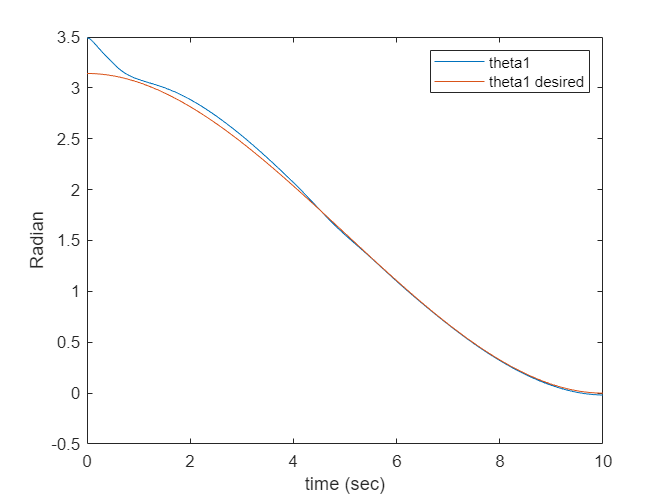

% ODE function
[t, y] = ode45(@adaptive_ode, [0, 10], [deg2rad(200), deg2rad(125), 0, 0, alpha_init(1), alpha_init(2), alpha_init(3), alpha_init(4), alpha_init(5), 0, 0]);

% Extract alpha values from the solution
alpha1_vals = y(:, 5);
alpha2_vals = y(:, 6);
alpha3_vals = y(:, 7);
alpha4_vals = y(:, 8);
alpha5_vals = y(:, 9);

% Get control input by differentiating the output from the ODE
tau = zeros(1, 2);
for i = 2:length(t)
    tau(length(tau)+1, 1) = (y(i, 10) - y(i-1, 10))/(t(i) - t(i-1));
    tau(length(tau), 2) = (y(i, 11) - y(i-1, 11))/(t(i) - t(i-1));
end
tau(1, :) = [];

% desired trajectory
th1_des = (pi*t.^3)/500 - (3*pi*t.^2)/100 + pi;
th1dot_des = (3*pi*t.^2)/500 - (3*pi*t)/50;
th2_des = (pi*t.^3)/1000 - (3*pi*t.^2)/200 + pi/2;
th2dot_des = (3*pi*t.^2)/1000 - (3*pi*t)/100;


% ploting graphs
figure;
plot(t,y(:,1));
xlabel('time (sec)');
ylabel('Radian');
hold 'on';
plot(t, th1_des);
legend('theta1', 'theta1 desired')

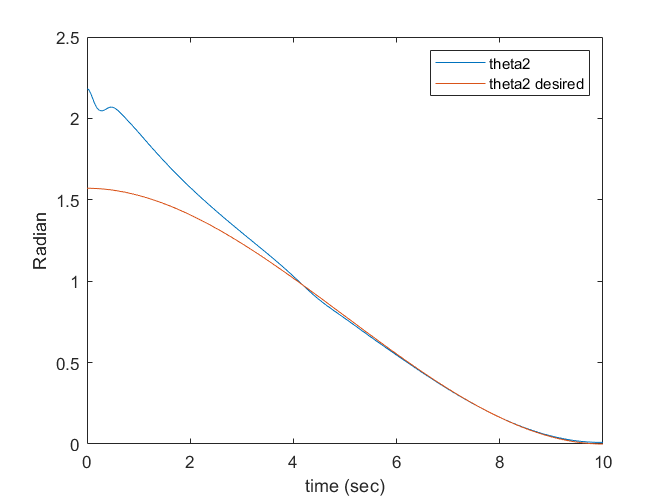


figure;
plot(t,y(:,2));
xlabel('time (sec)');
ylabel('Radian');
hold 'on';
plot(t, th2_des);
legend('theta2', 'theta2 desired')

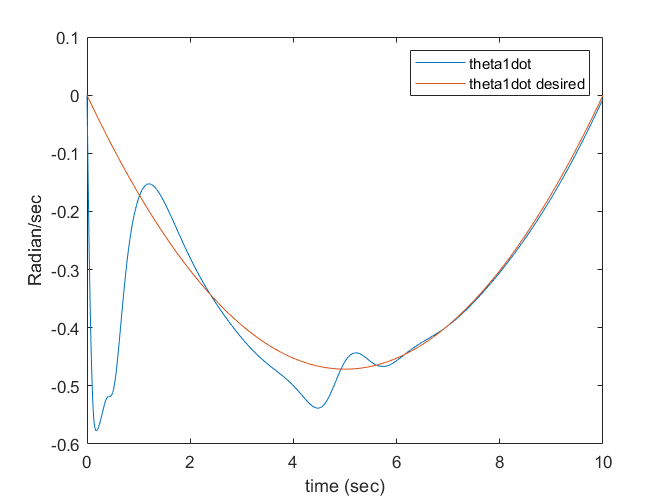


figure;
plot(t,y(:,3));
xlabel('time (sec)');
ylabel('Radian/sec');
hold 'on';
plot(t, th1dot_des);
legend('theta1dot', 'theta1dot desired')

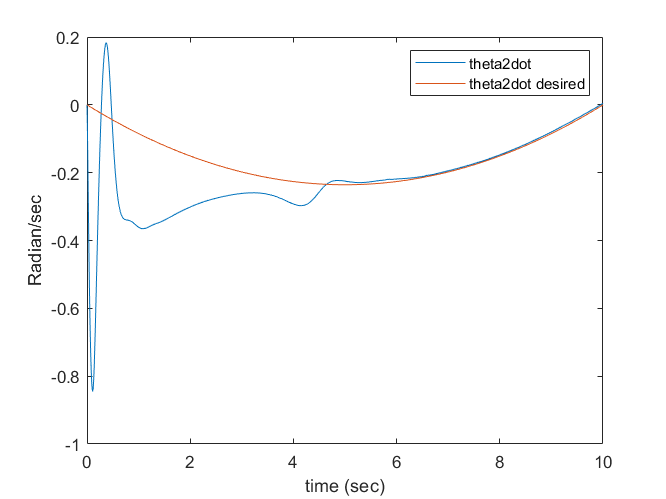


figure;
plot(t,y(:,4));
xlabel('time (sec)');
ylabel('Radian/sec');
hold 'on';
plot(t, th2dot_des);
legend('theta2dot', 'theta2dot desired')

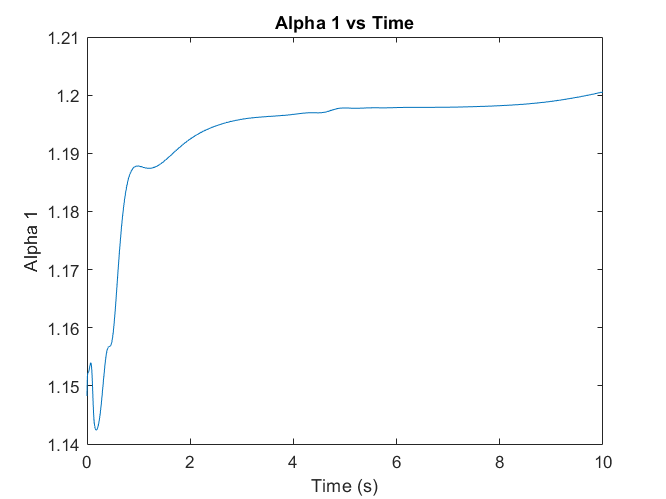


figure;
plot(t, alpha1_vals);
xlabel('Time (s)');
ylabel('Alpha 1');
title('Alpha 1 vs Time');

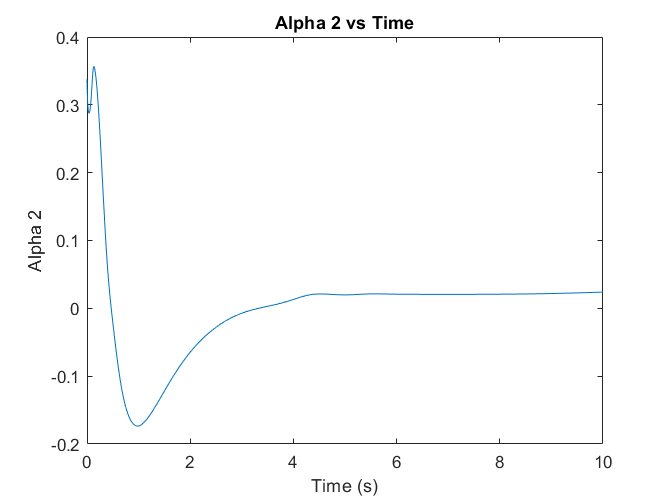


figure;
plot(t, alpha2_vals);
xlabel('Time (s)');
ylabel('Alpha 2');
title('Alpha 2 vs Time');

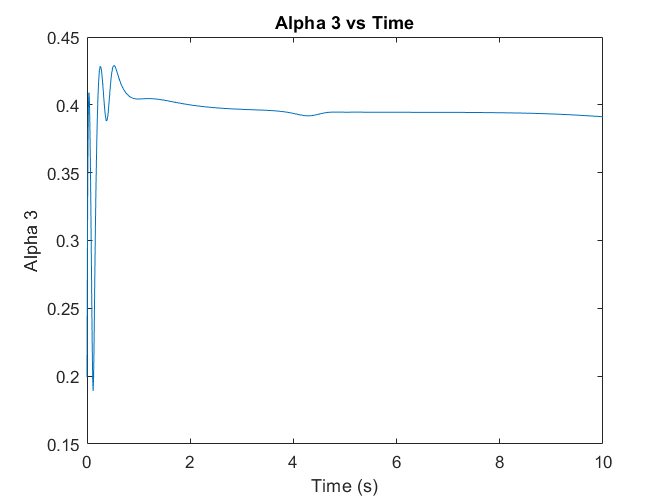


figure;
plot(t, alpha3_vals);
xlabel('Time (s)');
ylabel('Alpha 3');
title('Alpha 3 vs Time');

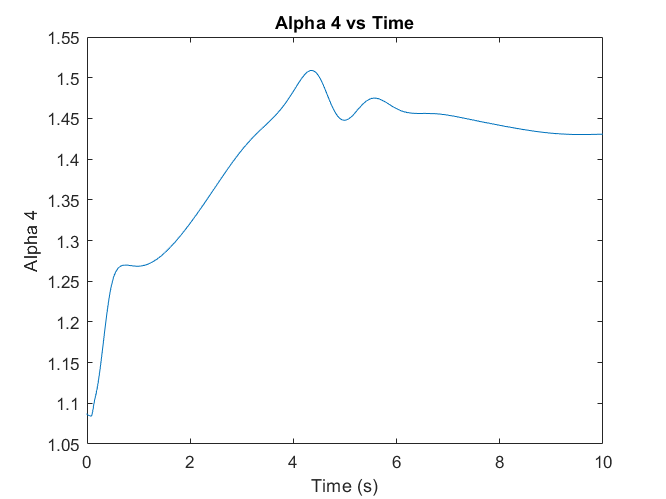


figure;
plot(t, alpha4_vals);
xlabel('Time (s)');
ylabel('Alpha 4');
title('Alpha 4 vs Time');

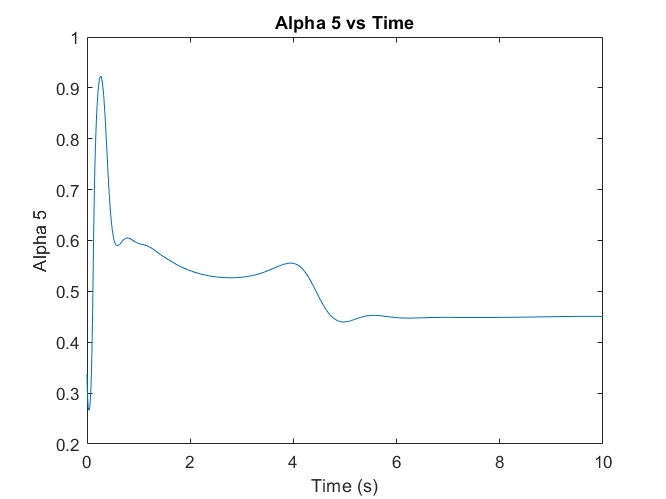


figure;
plot(t, alpha5_vals);
xlabel('Time (s)');
ylabel('Alpha 5');
title('Alpha 5 vs Time');

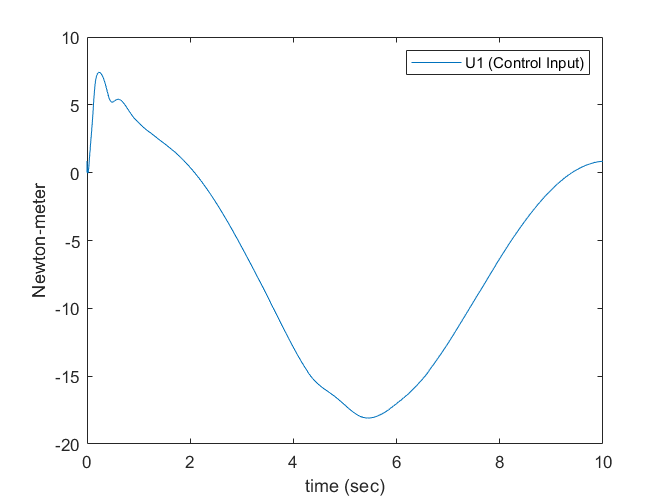


figure;
plot(t,tau(:,1));
xlabel('time (sec)');
ylabel('Newton-meter');
legend('U1 (Control Input)')

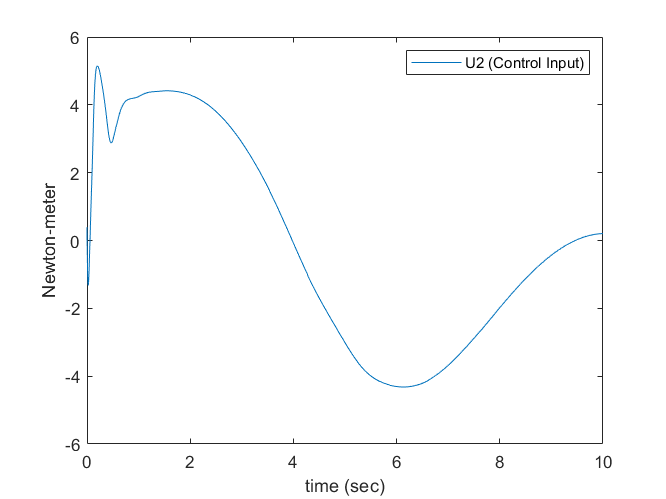


figure;
plot(t,tau(:,2));
xlabel('time (sec)');
ylabel('Newton-meter');
legend('U2 (Control Input)')

function xd = adaptive_ode(t, z)

% input matrix is (1, 11), T1 and T2 are also intergrated to calculate control inputs later
z = num2cell(z);
[theta1, theta2, theta1_dot, theta2_dot, alpha1, alpha2, alpha3, alpha4, alpha5, T1, T2] = deal(z{:});
alpha = [ alpha1; alpha2; alpha3; alpha4; alpha5];

% Adaptive control parameters
A = [ 0,   0,   1,  0; 
      0,   0,   0,  1; 
      0,   0,   0,  0; 
      0,   0,   0,  0];

B = [0, 0;
     0, 0;
     1, 0;
     0, 1];

eigenvalues = [-2, -2, -3, -3];

k = place(A, B, eigenvalues);

Acl = [zeros(2,2), eye(2); -k];

Q = eye(4)*1.2; 

P = lyap(Acl.', Q);

% error term
e = [theta1 - ((pi*t^3)/500 - (3*pi*t^2)/100 + pi);
     theta2 - ((pi*t^3)/1000 - (3*pi*t^2)/200 + pi/2);
     theta1_dot - ((3*pi*t^2)/500 - (3*pi*t)/50);
     theta2_dot - ((3*pi*t^2)/1000 - (3*pi*t)/100)];

% gamma matrix to get alpha_dot 
Gamma = eye(5)*0.35;  

% wraping theta1 and theta2
if (abs(theta1) > 2*pi) 
    theta1 = mod(theta1, (2*pi));
end

if (abs(theta2) > 2*pi) 
    theta2 = mod(theta2, (2*pi));
end

% calculating control input according to paramertic equation
Y =[ (3*pi*t^3)/125 - (159*pi*t^2)/500 - (51*pi*t)/125 - 12*theta1 - 7*theta1_dot + (597*pi)/50, - theta2^2*sin(theta2) - cos(theta2)*(- (3*pi*t^3)/50 + (159*pi*t^2)/200 + (51*pi*t)/50 + 24*theta1 + 12*theta2 + 14*theta1_dot + 7*theta2_dot - (597*pi)/20) - 2*theta1_dot*theta2_dot*sin(theta2),                              (3*pi*t^3)/250 - (159*pi*t^2)/1000 - (51*pi*t)/250 - 12*theta2 - 7*theta2_dot + (597*pi)/100, -(981*sin(theta1))/100, -(981*sin(theta1 + theta2))/100;
                                                                                          0,                                                               theta1_dot^2*sin(theta2) - cos(theta2)*(- (3*pi*t^3)/125 + (159*pi*t^2)/500 + (51*pi*t)/125 + 12*theta1 + 7*theta1_dot - (597*pi)/50), (9*pi*t^3)/250 - (477*pi*t^2)/1000 - (153*pi*t)/250 - 12*theta1 - 12*theta2 - 7*theta1_dot - 7*theta2_dot + (1791*pi)/100,                      0, -(981*sin(theta1 + theta2))/100];

T = Y*alpha;                                                                                   

T1 = double(T(1));
T2 = double(T(2));

% Calculating values of states
theta1_ddot =-(382000*T1 - 382000*T2 + 5433759*sin(theta1) + 171900*theta1_dot^2*sin(theta2) + 171900*theta2_dot^2*sin(theta2) - 600000*T2*cos(theta2) - 2648700*sin(theta1 + theta2)*cos(theta2) + 343800*theta1_dot*theta2_dot*sin(theta2) + 270000*theta1_dot^2*cos(theta2)*sin(theta2))/(270000*cos(theta2)^2 - 491443);
theta2_ddot = (1146000*T1 - 6292000*T2 - 22717017*sin(theta1 + theta2) + 16301277*sin(theta1) + 2831400*theta1_dot^2*sin(theta2) + 515700*theta2_dot^2*sin(theta2) + 25604100*cos(theta2)*sin(theta1) + 1800000*T1*cos(theta2) - 3600000*T2*cos(theta2) - 7946100*sin(theta1 + theta2)*cos(theta2) + 1031400*theta1_dot*theta2_dot*sin(theta2) + 1620000*theta1_dot^2*cos(theta2)*sin(theta2) + 810000*theta2_dot^2*cos(theta2)*sin(theta2) + 1620000*theta1_dot*theta2_dot*cos(theta2)*sin(theta2))/(3*(270000*cos(theta2)^2 - 491443));

% calculating Y again with theta_ddot1 and theta_ddot2 for updating alpha_dot

Y_update = [theta1_ddot, ...
     cos(theta2)*(2*theta1_ddot + theta2_ddot) - 2*sin(theta2)*theta1_dot*theta2_dot - sin(theta2)*theta2^2, ...
     theta2_ddot, ...
     -sin(theta1)*9.81, ...
     -sin(theta1 + theta2)*9.81; ...
     0, ...
     sin(theta2)*theta1_dot^2 + cos(theta2)*theta1_ddot, ...
     theta1_ddot + theta2_ddot, ... 
     0, ...
     -sin(theta1+theta2)*9.81];

% m_cap matrix to be updated in each loop
m_cap = [alpha(1) + 2*cos(theta2)*alpha(2), cos(theta2)*alpha(2); ...
         cos(theta2)*alpha(2) + alpha(3), alpha(3)];

phi = m_cap\Y_update;

% Calculating alpha_dot
alpha_dot = -Gamma\phi.'*B.'*P*e;  

xd = [theta1_dot; theta2_dot; theta1_ddot; theta2_ddot; alpha_dot(1); alpha_dot(2); alpha_dot(3); alpha_dot(4); alpha_dot(5); T1; T2];
xd = double(xd);
end